# Evaluación 1 José Fabián Molina Enríquez 175629

## Ejercicio 5

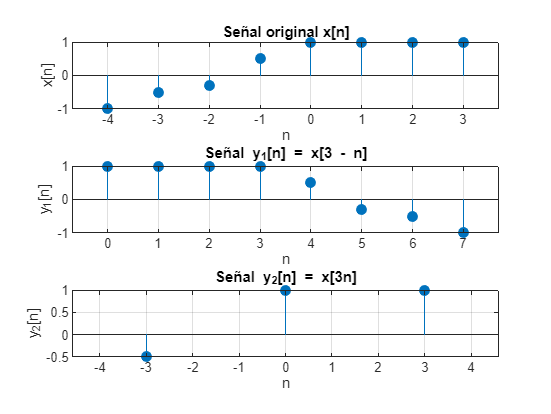

% Definir x[n]
n = -4:3;
x = [-1, -0.5, -0.3, 0.5, 1, 1, 1, 1];

% 1) Señal y1[n]
n1 = 3 - n;
y1 = x;
[y1_sorted, idx] = sort(n1);
y1 = y1(idx);

% 2) Señal y2[n]
n2 = n(mod(n,3) == 0);
y2 = x(ismember(n, n2));

% Graficar señales
figure;

% Señal original
subplot(3,1,1);
stem(n, x, 'filled');
xlabel('n'); ylabel('x[n]');
title('Señal original x[n]');
grid on;

% Señal y1[n]
subplot(3,1,2);
stem(y1_sorted, y1, 'filled');
xlabel('n'); ylabel('y_1[n]');
title('Señal y_1[n] = x[3 - n]');
grid on;

% Señal y2[n]
subplot(3,1,3);
stem(n2, y2, 'filled');
xlabel('n'); ylabel('y_2[n]');
title('Señal y_2[n] = x[3n]');
grid on;

## Ejercicio 6

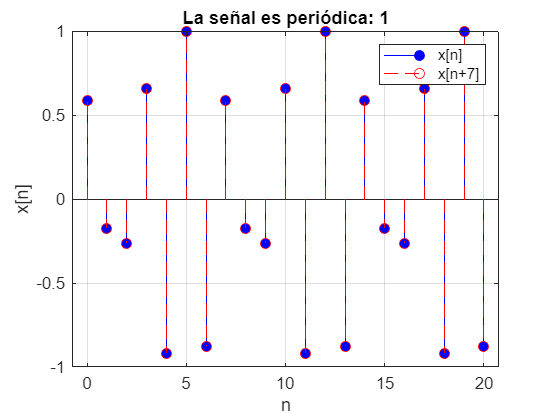

n = 0:20;

% Definir la señal x[n]
x_n = sin((6*pi/7) * n + pi/5);

% Desplazar la señal por N=7
x_n_shifted = sin((6*pi/7) * (n + 7) + pi/5);

% Comparar señales
is_periodic = all(abs(x_n - x_n_shifted) < 1e-10);

% Graficar la señal original y desplazada
figure;
stem(n, x_n, 'b', 'filled'); hold on;
stem(n, x_n_shifted, 'r--'); hold off;
xlabel('n');
ylabel('x[n]');
legend('x[n]', 'x[n+7]');
title(['La señal es periódica: ', num2str(is_periodic)]);
grid on;

## Ejercicio 7

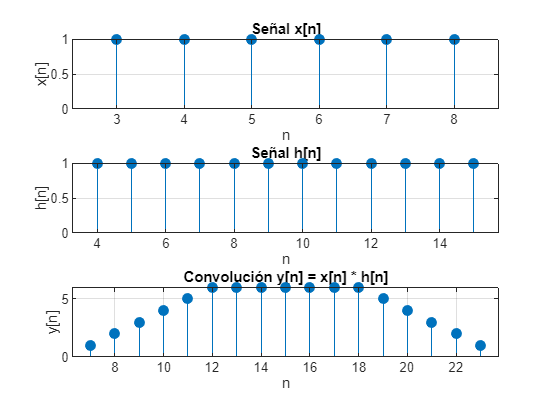

% Definir el rango de n
n_x = 3:8;  % Rango donde x[n] = 1
n_h = 4:15; % Rango donde h[n] = 1

% Definir las secuencias
x_n = ones(1, length(n_x)); 
h_n = ones(1, length(n_h));

% Calcular la convolución
y_n = conv(x_n, h_n); 


n_y = (n_x(1) + n_h(1)):(n_x(end) + n_h(end)); 

% Graficar las señales
figure;

subplot(3,1,1);
stem(n_x, x_n, 'filled');
xlabel('n'); ylabel('x[n]');
title('Señal x[n]');
grid on;

subplot(3,1,2);
stem(n_h, h_n, 'filled');
xlabel('n'); ylabel('h[n]');
title('Señal h[n]');
grid on;

subplot(3,1,3);
stem(n_y, y_n, 'filled');
xlabel('n'); ylabel('y[n]');
title('Convolución y[n] = x[n] * h[n]');
grid on;